## Q2 - Multivariate Gaussian

Generate N points (with N taking the values 10, $10^{2}$ , $10^{3}$ , $10^{4}$ , $10^{5}$) from a multivariate 2D Gaussian probability density function with mean µ = [1, 2]' and a covariance matrix C with the first row as [1.6250, −1.9486] and the second row as [−1.9486, 3.8750].

For each data sample of size N, compute the maximum-likelihood (ML) estimates of the mean and the covariance matrix.

Let, $X = \left[ \matrix{X_{1} \cr X_{2}}\right]$


$$C_{X} = E[XX^{T}] - E[X]E[X]^{T}$$


Let's define a new random vector $Y =  \left[\matrix{Y_{1} \cr Y_{2}}\right] =PX$

Thus, $C_{Y} = PC_{X}P^{T}$

We know every real symmetric matrix can be diagonalized by an orthogonal matrix. As $C_{X}$ is a real symmetric matrix, we can choose an orthogonal matirx $P$ such that $C_{Y}$ is a diagonal matrix. Further, we also know that the diagonal entries of $C_{Y}$ will be the eigenvalues of $C_{X}$ .

In the below computations, $V = P^{T} = P^{-1}$

As $C_{Y}$, which is the covariance matrix of $Y$ is a diagonal matrix, $Cov(Y_{1}, Y_{2}) = 0$.

As $Y$ is a 2-D gaussian, Covariance=0 implies independence of $Y_{1}$ and $Y_{2}$.

Note that the above statement is not true for some general random variable.

So now, we can generate random draws from $Y_{1}$ and $Y_{2}$ using $\texttt{randn(.)}$ as both are independent.

We will get $X$ by taking inverse transform as,


$$X = P^{-1}Y = VY$$


rng(0);

mu = [1; 2]; % true mean of X
C = [1.6250 -1.9486; -1.9486 3.8750]; % true covariance of X

[V, Cy] = eig(C); % transformation of covX into covY
muY = V'*mu; % mean of Y

% array to store values of N
Nvals = zeros(5);
Nvals(1) = 10;
Nvals(2) = 100;
Nvals(3) = 1000;
Nvals(4) = 10000;
Nvals(5) = 100000;

% to store samples of X
sample1 = zeros(2, 10); % for N=10
sample2 = zeros(2, 100); % for N=100
sample3 = zeros(2, 1000); % for N=1000
sample4 = zeros(2, 10000); % for N=10000
sample5 = zeros(2, 100000); % for N=100000

means = zeros(2, 5); % to store sample mean
covariances = zeros(2, 2, 5); % to store sample covariance

We want to do $X=VY$ by drawing samples from Y

To draw samples from $Y$, we will

- Draw samples from standard normal distribution

- Scale it by factor of standard deviation and add mean to it

for i=1:1:5
    N = Nvals(i);

    for j=1:1:N
        Y = [randn()*sqrt(Cy(1,1)); randn()*sqrt(Cy(2,2))] + muY; % scaling and adding of mean
        X = V*Y; % inverse transformation
        
        % storing of sample values
        if(i==1)
            sample1(:, j) = X;
        end
        if(i==2)
            sample2(:, j) = X;
        end
        if(i==3)
            sample3(:, j) = X;
        end
        if(i==4)
            sample4(:, j) = X;
        end
        if(i==5)
            sample5(:, j) = X;
        end
    end
    
    mean = zeros(2,1);
    cov = zeros(2,2);
    
    % calculation of sample mean and sample covariance
    if(i==1)
        mean = sum(sample1, 2);
        mean = mean/N;
        for j=1:1:N
            cov(:,:) = cov(:,:) + (sample1(:,j)-mean)*(sample1(:,j)-mean)';
        end

        cov = cov/N;
    end
    if(i==2)
        mean = sum(sample2, 2);
        mean = mean/N;
        for j=1:1:N
            cov(:,:) = cov(:,:) + (sample2(:,j)-mean)*(sample2(:,j)-mean)';
        end

        cov = cov/N;
    end
    if(i==3)
        mean = sum(sample3, 2);
        mean = mean/N;
        for j=1:1:N
            cov(:,:) = cov(:,:) + (sample3(:,j)-mean)*(sample3(:,j)-mean)';
        end

        cov = cov/N;
    end
    if(i==4)
        mean = sum(sample4, 2);
        mean = mean/N;
        for j=1:1:N
            cov(:,:) = cov(:,:) + (sample4(:,j)-mean)*(sample4(:,j)-mean)';
        end

        cov = cov/N;
    end
    if(i==5)
        mean = sum(sample5, 2);
        mean = mean/N;
        for j=1:1:N
            cov(:,:) = cov(:,:) + (sample5(:,j)-mean)*(sample5(:,j)-mean)';
        end

        cov = cov/N;
    end

    means(:, i) = mean; % storing of mean
    covariances(:, :, i) = cov; % storing of covariance
end

% displaying mean and covariance for each N
for i=1:1:5
    disp("##### For N=" + Nvals(i));
    disp("Mean :");
    means(:,i)
    disp("Covariance :");
    covariances(:,:,i)
end

##### For N=10


Mean :


ans =    -0.3284
    3.8600


Covariance :


ans =     3.3055   -3.3554
   -3.3554    6.1815


##### For N=100


Mean :


ans =     1.0656
    1.9989


Covariance :


ans =     1.4690   -1.8433
   -1.8433    3.9425


##### For N=1000


Mean :


ans =     0.9954
    1.9495


Covariance :


ans =     1.6703   -1.9207
   -1.9207    3.6643


##### For N=10000


Mean :


ans =     0.9957
    2.0136


Covariance :


ans =     1.6301   -1.9237
   -1.9237    3.7641


##### For N=100000


Mean :


ans =     0.9998
    2.0025


Covariance :


ans =     1.6140   -1.9369
   -1.9369    3.8755


Error in mean is defined as, $\frac{||\mu - \hat{\mu_{N}}||_{2}}{||\mu||_{2}} = \frac{(\mu - \hat{\mu_{N}})^{T}(\mu - \hat{\mu_{N}})}{\mu^{T}\mu}$

Error in covariance is defined as, $\frac{||C-\hat{C_{N}}||_{Fro}}{||C||_{Fro}} = \frac{\sqrt{\text{sum of squares of entries of } C-\hat{C_{N}}}}{\sqrt{\text{sum of squars of entries of } C}}$

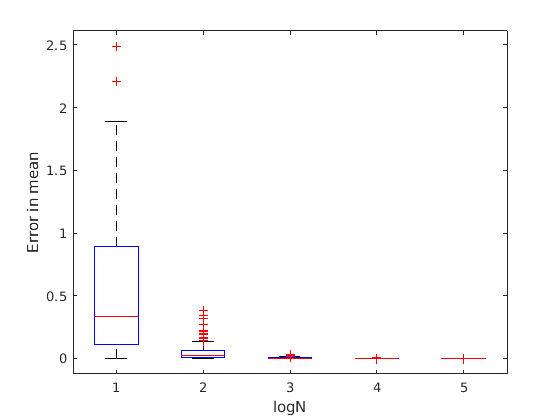

% store erros for of each experiment for each N
errorInMeans = zeros(100, 5);
errorInCov = zeros(100, 5);

for i=1:1:5
    N = Nvals(i);

    for k=1:1:100
        for j=1:1:N
            Y = [randn()*sqrt(Cy(1,1)); randn()*sqrt(Cy(2,2))] + muY; % drawing random samples from Y
            X = V*Y; % taking inverse transform
    
            if(i==1)
                sample1(:, j) = X;
            end
            if(i==2)
                sample2(:, j) = X;
            end
            if(i==3)
                sample3(:, j) = X;
            end
            if(i==4)
                sample4(:, j) = X;
            end
            if(i==5)
                sample5(:, j) = X;
            end
        end
        
        mean = zeros(2,1);
        cov = zeros(2,2);
    
        if(i==1)
            mean = sum(sample1, 2);
            mean = mean/N;
            for j=1:1:N
                cov(:,:) = cov(:,:) + (sample1(:,j)-mean)*(sample1(:,j)-mean)';
            end
    
            cov = cov/N;
        end
        if(i==2)
            mean = sum(sample2, 2);
            mean = mean/N;
            for j=1:1:N
                cov(:,:) = cov(:,:) + (sample2(:,j)-mean)*(sample2(:,j)-mean)';
            end
    
            cov = cov/N;
        end
        if(i==3)
            mean = sum(sample3, 2);
            mean = mean/N;
            for j=1:1:N
                cov(:,:) = cov(:,:) + (sample3(:,j)-mean)*(sample3(:,j)-mean)';
            end
    
            cov = cov/N;
        end
        if(i==4)
            mean = sum(sample4, 2);
            mean = mean/N;
            for j=1:1:N
                cov(:,:) = cov(:,:) + (sample4(:,j)-mean)*(sample4(:,j)-mean)';
            end
    
            cov = cov/N;
        end
        if(i==5)
            mean = sum(sample5, 2);
            mean = mean/N;
            for j=1:1:N
                cov(:,:) = cov(:,:) + (sample5(:,j)-mean)*(sample5(:,j)-mean)';
            end
    
            cov = cov/N;
        end

        errorInMeans(k, i) = (mu - mean)'*(mu - mean); % error in mean as defined earlier
        
        % calculating error in covariance as defined earlier
        num = 0;
        den = 0;
        for p=1:1:2
            for q=1:1:2
                num = num + (C(p,q)-cov(p,q))*(C(p,q)-cov(p,q));
                den = den + C(p,q)*C(p,q);
            end
        end
        errorInCov(k, i) = sqrt(num)/sqrt(den);
    end
end

% plotting boxplots of errors
figure,
boxplot(errorInMeans, 'Labels', {'1', '2', '3', '4', '5'});
xlabel("logN");
ylabel("Error in mean");

figure,
boxplot(errorInCov, 'Labels', {'1', '2', '3', '4', '5'});

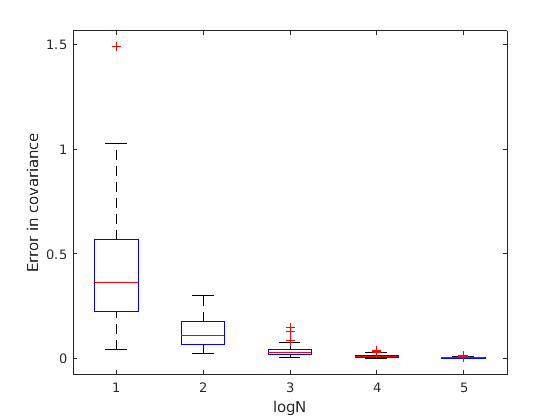

xlabel("logN");
ylabel("Error in covariance");

Plotting 'Scatter Plots' of randomly drawn samples of $X$

The method is exact same as done in the first part

means = zeros(2, 5);
covariances = zeros(2, 2, 5);

for i=1:1:5
    N = Nvals(i);

    for j=1:1:N
        Y = [randn()*sqrt(Cy(1,1)); randn()*sqrt(Cy(2,2))] + muY;
        X = V*Y;

        if(i==1)
            sample1(:, j) = X;
        end
        if(i==2)
            sample2(:, j) = X;
        end
        if(i==3)
            sample3(:, j) = X;
        end
        if(i==4)
            sample4(:, j) = X;
        end
        if(i==5)
            sample5(:, j) = X;
        end
    end
    
    mean = zeros(2,1);
    cov = zeros(2,2);

    if(i==1)
        mean = sum(sample1, 2);
        mean = mean/N;
        for j=1:1:N
            cov(:,:) = cov(:,:) + (sample1(:,j)-mean)*(sample1(:,j)-mean)';
        end

        cov = cov/N;
    end
    if(i==2)
        mean = sum(sample2, 2);
        mean = mean/N;
        for j=1:1:N
            cov(:,:) = cov(:,:) + (sample2(:,j)-mean)*(sample2(:,j)-mean)';
        end

        cov = cov/N;
    end
    if(i==3)
        mean = sum(sample3, 2);
        mean = mean/N;
        for j=1:1:N
            cov(:,:) = cov(:,:) + (sample3(:,j)-mean)*(sample3(:,j)-mean)';
        end

        cov = cov/N;
    end
    if(i==4)
        mean = sum(sample4, 2);
        mean = mean/N;
        for j=1:1:N
            cov(:,:) = cov(:,:) + (sample4(:,j)-mean)*(sample4(:,j)-mean)';
        end

        cov = cov/N;
    end
    if(i==5)
        mean = sum(sample5, 2);
        mean = mean/N;
        for j=1:1:N
            cov(:,:) = cov(:,:) + (sample5(:,j)-mean)*(sample5(:,j)-mean)';
        end

        cov = cov/N;
    end

    means(:, i) = mean;
    covariances(:, :, i) = cov;
end

Scatter Plot along with the line showing Principal Mode of Variation

Principal mode of variation is in the direction of eigenvector corresponding to largest eigenvalue

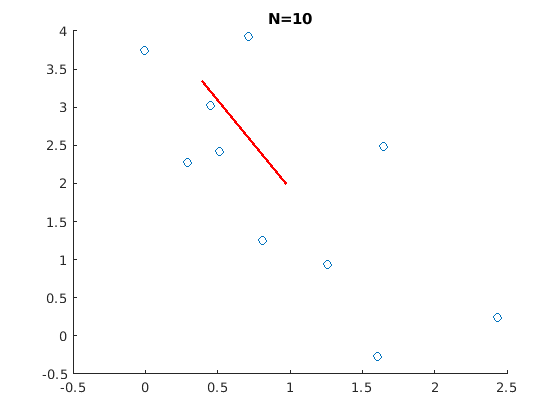

figure,
hold on;
scatter(sample1(1,:), sample1(2,:)); % scatter plot of random draws
[eigVec, eigVal] = eig(covariances(:,:,1)); % calculating eigenvectors and eigenvalues
[d, ind] = sort(diag(eigVal), 'descend'); % sorting eigenvalues in descending order
p = means(:,1) + sqrt(d(1))*(eigVec(:,ind(1))); % eigenvector corresponding to largest eigenvalue
scatter(linspace(means(1,1), p(1,1), 10000), linspace(means(2,1), p(2,1), 10000), 5, 'red', 'filled'); % line of length sqrt(eigenValue) in direction of principal eigenvector
title("N=10");
hold off;

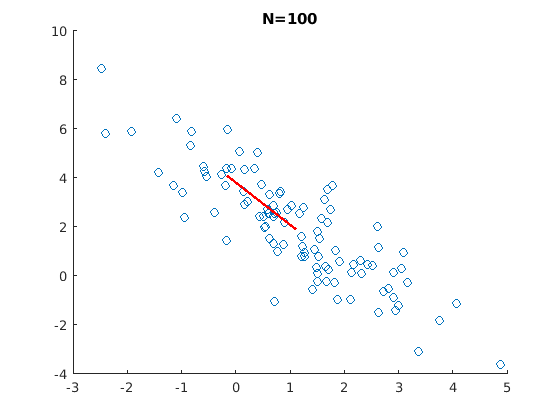


% same as above
figure,
hold on;
scatter(sample2(1,:), sample2(2,:));
[eigVec, eigVal] = eig(covariances(:,:,2));
[d, ind] = sort(diag(eigVal), 'descend');
p = means(:,2) + sqrt(d(1))*(eigVec(:,ind(1)));
scatter(linspace(means(1,2), p(1,1), 10000), linspace(means(2,2), p(2,1), 10000), 5, 'red', 'filled');
title("N=100");
hold off;

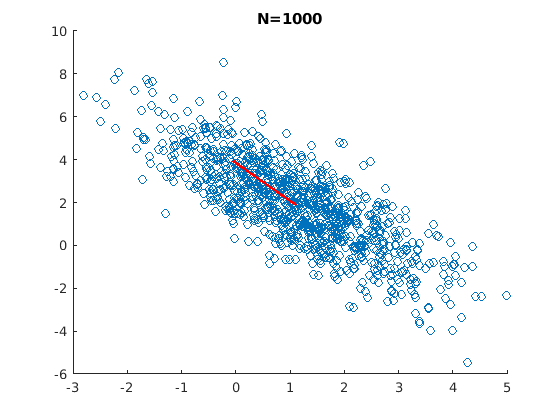


figure,
hold on;
scatter(sample3(1,:), sample3(2,:));
[eigVec, eigVal] = eig(covariances(:,:,3));
[d, ind] = sort(diag(eigVal), 'descend');
p = means(:,3) + sqrt(d(1))*(eigVec(:,ind(1)));
scatter(linspace(means(1,3), p(1,1), 10000), linspace(means(2,3), p(2,1), 10000), 5, 'red', 'filled');
title("N=1000");
hold off;

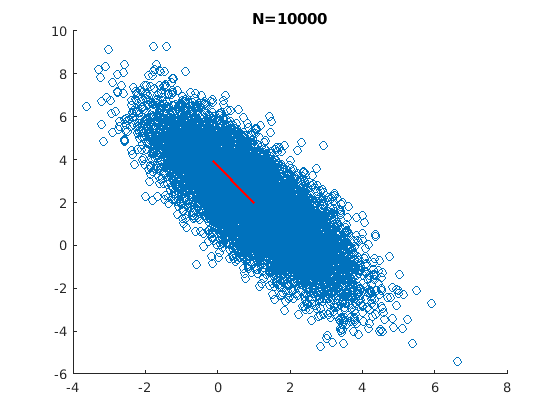


figure,
hold on;
scatter(sample4(1,:), sample4(2,:));
[eigVec, eigVal] = eig(covariances(:,:,4));
[d, ind] = sort(diag(eigVal), 'descend');
p = means(:,4) + sqrt(d(1))*(eigVec(:,ind(1)));
scatter(linspace(means(1,4), p(1,1), 10000), linspace(means(2,4), p(2,1), 10000), 5, 'red', 'filled');
title("N=10000");
hold off;

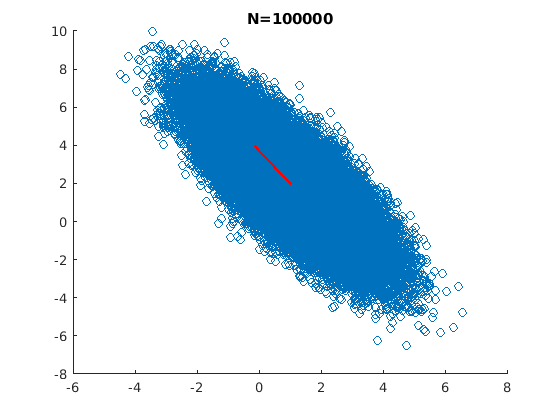


figure,
hold on;
scatter(sample5(1,:), sample5(2,:));
[eigVec, eigVal] = eig(covariances(:,:,5));
[d, ind] = sort(diag(eigVal), 'descend');
p = means(:,5) + sqrt(d(1))*(eigVec(:,ind(1)));
scatter(linspace(means(1,5), p(1,1), 10000), linspace(means(2,5), p(2,1), 10000), 5, 'red', 'filled');
title("N=100000");
hold off;